## Bird flapping movement simulation

### constants：

c=2.99792458e8;  % light speed

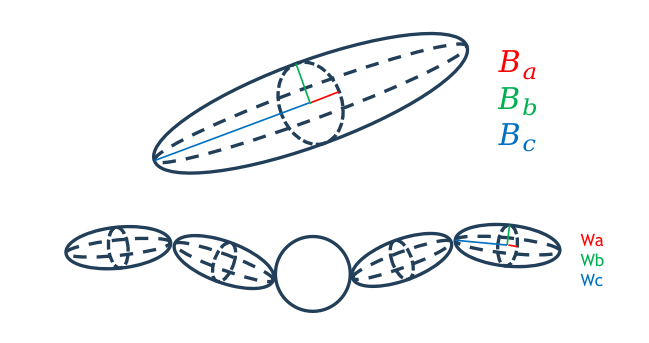

### Body and Wing Dimensions:

% body
Ba = 0.1;
Bb = 0.1;
Bc = 1.0;
% wing
Wa = 0.05; 
Wb = 0.05; 
Wc = 0.25;

parameters for birds' body:

$B_a$: Body semi-axis length a (0.05 - 0.3 m)

$B_b$: Body semi-axis length b (0.05 - 0.3 m)

$B_c$: Body semi-axis length c (0.5 - 2.0 m)

parameters for birds' wings:

$W_a$: Wing semi-axis length a (0.01 - 0.1 m)

$W_b$: Wing semi-axis length b (0.01 - 0.1 m)

$W_c$: Wing semi-axis length c (0.1 - 0.5 m)

### Parameters for birds

Assume a simple kinematic model of a bird's wing with two connected parts, as shown in the figure:

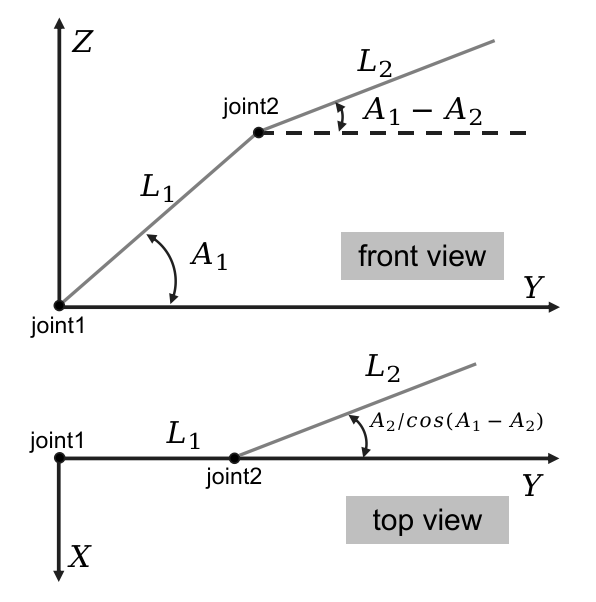

Input parameters from the user：

- flapping frequency $$f_{flap}$$ (1 - 20 Hz),

- length of upper arm $L_1$(0.1 - 1.0 m),

- amplitude of flapping angel for upper arm (in degree) $A_1$ (20 - 60$\degree$),

- lag flapping angle for upper arm (in degree) $\psi_{10}$ (0 - 30$\degree$),

- length of Forearm $L_2$ (0.1 - 1.0 m),

- amplitude of flapping angel for forearm (in degree) $A_2$ (15 - 45$\degree$),

- lag flapping angle for forearm (in degree) $\psi_{20}$ (20 - 60$\degree$),

- Forearm sweep angle $C_{2}$ (10 - 40$\degree$)。

F0 = 5.0; % flapping frequency
A1 = 40; % amplitude of flapping angel in degree
ksi10 = 15; % lag flapping angle in degree
L1 = 0.5; % length of segment 1

A2 = 30; % amplitude of segment2 flapping angle
ksi20 = 40; % lag flapping angle in degree
L2 = 0.5; % length of segment 2
C2 = 20; % amplitude of segment2 twisting angle

### Parameters for radar

Radar parameters include time duration, number of samples, wavelength, range resolution, radar position

T = 1; % time duration
nt = 15000; % number of samples
lambda = 0.0032;   % wavelength of transmitted radar signal
rangeres = 0.05;  % designed range resolution
radarloc = [20, 0, -10];  % radar location

$T$: time duration (1 - 10 s)

$nt$: number of samples (10000 - 100000)

$lambda$: wavelength of transmitted radar signal (0.001 - 0.1 m), which is controled by frequency of the radar in APP

$rangeres$: designed range resolution of radar (0.01 - 0.5 m)

$radarloc$: radar location in the coordinate system.

### Parameters for bird's movement

The bird is initially located at the origin of an inertial coordinate system. Its velocities along the three coordinate axes are $v_x$, $v_y$, and $v_z$ respectively. The bird's flight direction points in the direction of its velocity vector. The bird's motion can be decomposed into two components: the main translational motion of its body and the micro-motion of the target.

Two coordinate systems are involved in this scenario: the body-fixed coordinate system and the inertial coordinate system. The bird's wing-flapping motion is more conveniently calculated in the body-fixed coordinate system. However, we ultimately need the coordinates of the bird's wings in the inertial coordinate system. Therefore, coordinate rotation and translation are used to transform from the body-fixed system to the inertial system.

Assuming the coordinates of a scattering center on the target in the body-fixed coordinate system are $$\left( x,y,z \right)$$`，`and the bird's flight direction is aligned with its velocity vector $$\text{v}=\left( {{v}_{x}},{{v}_{y}},{{v}_{z}} \right)$$, the coordinates of this scattering center in the inertial coordinate system after the bird has flown for time t can be calculated through the following steps: 

`1. `Calculate the unit vector of the velocity vector

	
$$\[\mathbf{v_{\text{unit}}} = \frac{\mathbf{v}}{|\mathbf{v}|}\]$$


where $$\mathbf{v}$ $is the velocity vector, $$\mathbf{v_{\text{unit}}}$$ is the normalized velocity vector (unit vector).

`2. `Set the initial direction vector

The initial direction vector is set as the unit vector along the x-axis:

	
$$d_0 =\left\lbrack \begin{array}{c}
1\\
0\\
0
\end{array}\right\rbrack$$


`3. `Calculate the rotation axis

The rotation axis is determined by the cross product of the initial direction vector and the velocity unit vector`：`

	
$$\[\mathbf{r_{\text{axis}}} = \frac{\mathbf{d_0} \times \mathbf{v_{\text{unit}}}}{|\mathbf{d_0} \times \mathbf{v_{\text{unit}}}|}\]$$


If the velocity vector aligns with the initial direction vector, no rotation is needed, only translation is required.

`4. `Calculate the rotation angle

The rotation angle is calculated using the dot product of the initial direction vector and the velocity unit vector.

	
$$\[\theta = \cos^{-1}(\mathbf{d_0} \cdot \mathbf{v_{\text{unit}}})\]$$


`5. `Construct the rotation matrix

Construct the rotation matrix $R$ using Rodrigues' rotation formula:


$$\mathbf{K} = \left[\begin{array}{c}0 & -r_{\text{axis},3} & r_{\text{axis},2} \\r_{\text{axis},3} & 0 & -r_{\text{axis},1} \\-r_{\text{axis},2} & r_{\text{axis},1} & 0 \end{array}\right]$$



$$\[\mathbf{R} = \mathbf{I} + \sin(\theta) \mathbf{K} + (1 - \cos(\theta)) \mathbf{K}^2\]$$


where $$\mathbf{I}$$ is the identity matrix, and $$\mathbf{K}$$ is a matrix constructed based on the rotation axis.

`6. `Apply rotation and translation

For each point, apply rotation to its coordinates and then perform translation:

	
$$\[\mathbf{p_{\text{new}}} = \mathbf{R} \cdot \mathbf{p} + \mathbf{v} \cdot t\]$$


where $$\mathbf{p}$ $is the original coordinate, $$\mathbf{p_{\text{new}}}$ $is the updated coordinate, $$\mathbf{v}$$ is the velocity vector, $$t$ $is the time.

`7. `Obtain the new coordinates:

Finally, we obtain the updated coordinate matrix X_new, representing the new coordinates after rotation and translation.

vx = 0; % forward translation velocity
vy = 0;
vz = 0;

$v_x$: Forward translation velocity x-component (-30 - 30 m/s)

$v_y$: Forward translation velocity y-component (-30 - 30 m/s)

$v_z$: Forward translation velocity z-component (-30 - 30 m/s)

## Simulation

import mypackage.Bird

#### Create a bird object

To facilitate the simulation of bird flapping motion, we establish a class named Bird.

myBird = Bird(T, nt, lambda, rangeres, radarloc,...
              F0, A1, ksi10, L1, A2, ksi20, L2, C2, ...
              vx, vy, vz);

Calculate the positions of scattering centers for the `myBird` object and plot the bird's motion trajectory. Assume that at the initial moment, the inertial coordinate system and the body coordinate system coincide, the velocities in all three directions are 0, and at this time, the wing motion in the inertial coordinate system is consistent with that in the body coordinate system.

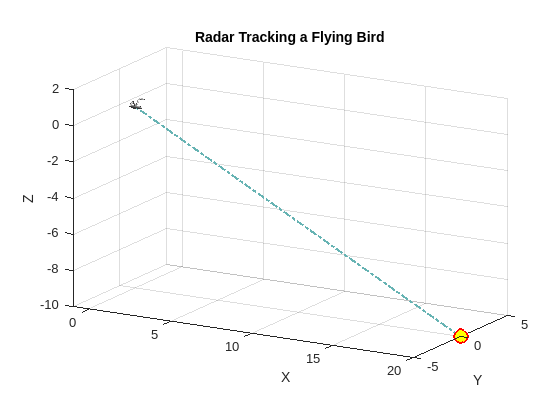

myBird.drawRadarTrackingaFlyingBird()

Calculate the radar echo and plot the one-dimensional range profile.

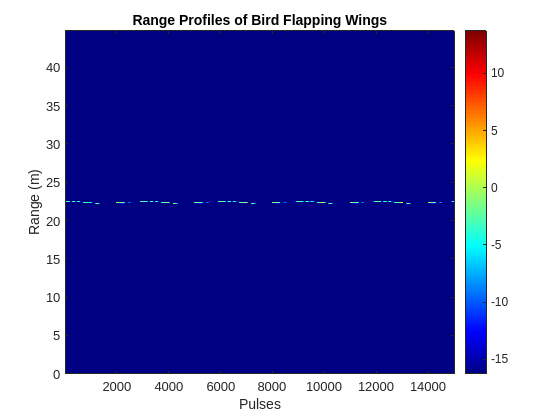

myBird.drawRangeProfiles()

Calculate the micro-Doppler spectrum of the bird's flapping motion.

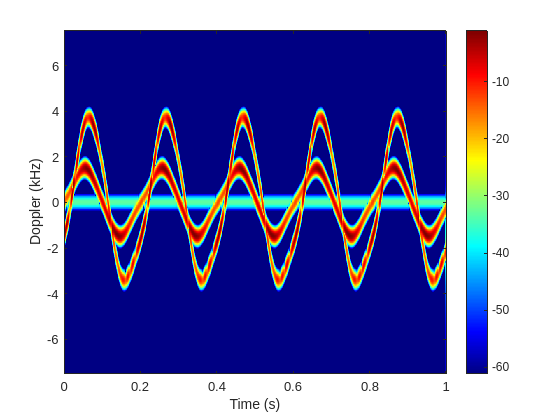

myBird.drawmicroDopplersignature()

#### Set the velocity in the x direction to 1

when $v_x = 1$,

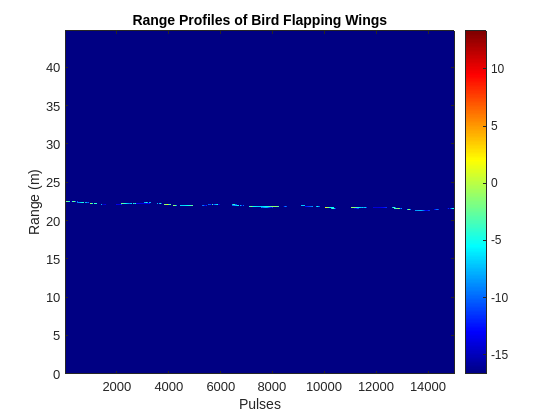

vx = 1;
myBird1 = Bird(T, nt, lambda, rangeres, radarloc,...
              F0, A1, ksi10, L1, A2, ksi20, L2, C2, ...
              vx, vy, vz);
myBird1.drawRangeProfiles()

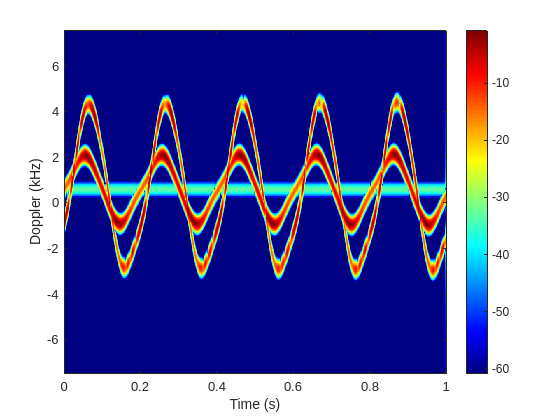

myBird1.drawmicroDopplersignature()

#### Flapping Frequency 7Hz

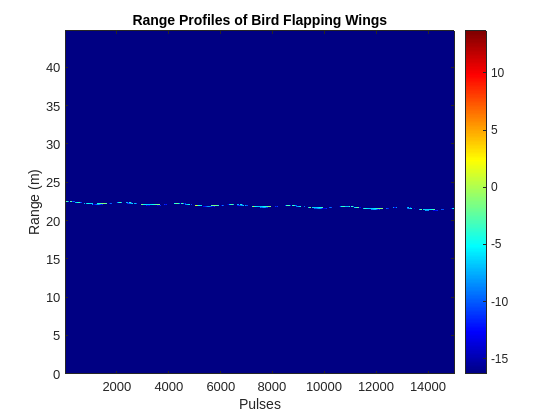

F0 = 7;
vx = 1;
myBird2 = Bird(T, nt, lambda, rangeres, radarloc,...
              F0, A1, ksi10, L1, A2, ksi20, L2, C2, ...
              vx, vy, vz);


myBird2.drawRangeProfiles()

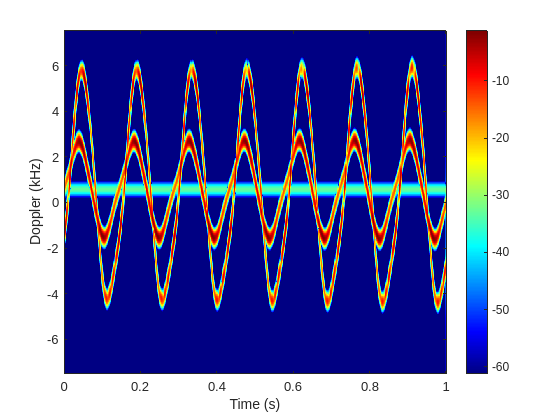

myBird2.drawmicroDopplersignature()

### A complete example

T = 1; % time duration
nt = 15000; % number of samples
lambda = 0.0032;   % wavelength of transmitted radar signal
rangeres = 0.05;  % designed range resolution
radarloc = [20, 0, -10];  % radar location
% 
F0 = 5.0; % flapping frequency
A1 = 40; % amplitude of flapping angel in degree
ksi10 = 15; % lag flapping angle in degree
L1 = 0.5; % length of segment 1

A2 = 30; % amplitude of segment2 flapping angle
ksi20 = 40; % lag flapping angle in degree
L2 = 0.5; % length of segment 2
C2 = 20; % amplitude of segment2 twisting angle

vx = 0; % forward translation velocity
vy = 0;
vz = 0;

myBird3 = Bird(T, nt, lambda, rangeres, radarloc,...
              F0, A1, ksi10, L1, A2, ksi20, L2, C2, ...
              vx, vy, vz);


myBird3.drawRangeProfiles()

myBird3.drawmicroDopplersignature()